## MA 402 Project 1

### Friday March 11, 2022

### Andrea Stancescu, Jenna Varnell, Omry Bewster

% Andrea Stancescu, Jenna Varnell, Omry Brewster
% MA 402 Project 1 
% 3-11-2022
% MATLAB .mlx file with integrated text and code

### 1. Introduction

Chemical reactions can be simulated by equations that relate the changing quantities of the reaction. As the derivative of a function provides the rate at which that function is changing with respect to its independent variable, the equations describing these phenomena often involve one or more derivatives, and we refer to them as differential equations

The purpose of this project is to model the Michaelis-Menten system which is a model of an enzyme reaction. The four components of the enzyme reaction are an enzyme (E), a substrate (S), the enzyme-substrate compound (C), and the product of the reaction (P). 

The Michaelis-Menten system is represented below as:

#### 
$$E+S\underset{\theta_1 }{\overset{\theta_2 }{\iff} } C\overset{\theta_3 }{\longrightarrow} E+P$$


Throughout the project, we will assume that the reaction rates are proportional to the product of the concentrations of the reactions which will lead us to the following system of four differential equations:

#### $\begin{array}{l}
{\left\lbrack S\right\rbrack }^{\prime } \left(t\right)\;=-\theta_1 \left\lbrack E\right\rbrack \left\lbrack S\right\rbrack +\theta_2 \left\lbrack C\right\rbrack \\
{\left\lbrack E\right\rbrack }^{\prime } \left(t\right)=-\theta_1 \left\lbrack E\right\rbrack \left\lbrack S\right\rbrack +\left(\theta_2 +\theta_3 \right)\left\lbrack C\right\rbrack \\
{\left\lbrack C\right\rbrack }^{\prime } \left(t\right)={\;\theta }_1 \left\lbrack E\right\rbrack \left\lbrack S\right\rbrack -\left(\theta_2 +\theta_3 \right)\left\lbrack C\right\rbrack \\
{\left\lbrack P\right\rbrack }^{\prime } \left(t\right)=\theta_3 \left\lbrack C\right\rbrack \;\;
\end{array}$                                                                                                   (1)

Throughout the project we will also use $\theta_1$ to signify the forward reaction rate coefficient, $\theta_2 \;$to signify the reverse reaction rate coefficient, and $\theta_3$ to represent the catalytic reaction rate coefficient. Furthermore, we will also use the following initial values when solving the system of equations using differential methods and Euler's method:

####                                                                                                                              $\begin{array}{l}
S_0 =5*{10}^{-2\;} \;\frac{\textrm{mol}}{L}\\
E_0 =2*{10}^{-2} \;\frac{\textrm{mol}}{L}\\
C_0 =0\;\frac{\textrm{mol}}{L}\\
P_0 =0\;\frac{\textrm{mol}}{L}
\end{array}$                                                                                                                        (2)

We will be solving the system of differential equations using computational numerical ordinary differential equation solvers as well as Euler's Method. In Section 2, we use MATLAB's built in ode45() function to solve th system of first order differential equations over the time span of [0,30] and the initial values listed above. In Section 3, we use Euler's method with 3 different step sizes to approximate the solution to the initial value problem. In Sections 4 and 5 we repeat the methods used in Sections 2 and 3 respectively while sampling the reaction rates from lognormal distributions and additionally outputing an expected value and a confidence interval for the final product of the reaction, $\left\lbrack P\right\rbrack$. 

### 2 Differentiation Method 

Solutions to ordinary differential equations cannot be uniquely determined without some provided initial value. We are often given a first order equation of the following form with the corresponding initial value

$y{\;}^{\prime } \left(t\right)=f\left(t,y\left(t\right)\right)$    ;     $\left(0,y\left(0\right)\right)$  

Then from Taylor's Theorem we have that


$$y\left(x\right)=y\left(0\right)+y\prime \left(0\right)x+\frac{1}{2}y\prime \prime \left(0\right)x^2 +\frac{1}{6}y^{\left(3\right)} \left(0\right)x^3 +\dots$$


which we ultimately wish to solve for the respective coefficients. Thus, we will differentiate our given differential equation and plug in our initial value of $t=0$ to approximate the solution:


$$y\prime \prime \left(0\right)=\frac{\partial }{\partial t}f\left(0,y\left(0\right)\right)+\frac{\partial }{\partial y}f\left(0,y\left(0\right)\right)*y^{\prime } \left(0\right)$$


#### 2.1 Results

Since we are given the values of the reaction rate coefficients, $\theta_1 \;,\theta_{2\;} \;,\textrm{and}\;\theta_3$ , we can solve the initial value problem by setting up a system of four differential equations. Consequently, our anonymous function, ddt, takes in arguments t and x and returns the system given in (1).

The ode45() function in MATLAB takes in ddt, the 4x1 matrix of the system of four differential equations, tspan = [0,30] which represents the time interval over which we wish to model the chemical reaction, and the initial values as given in (2) which are passed in via a 4x1 vector.

The resulting outputted plot seen in figure 1 shows that the concentration of the enzyme (seen in dark blue) and the enzyme-substrate compound (seen in light blue) are inversely proportional to each other. The concentration of the enzyme reaches its peak around a time of t = 5 meanwhile, the concentration of the enzyme-substrate compound reaches its minimum at this time. Furthermore, the substrate the product concentrations are inversely proportional as seen by the red and green lines. This intuitively shows that the product is increasing as a result of the substrate decreasing which signifies the progression of the experiment.  

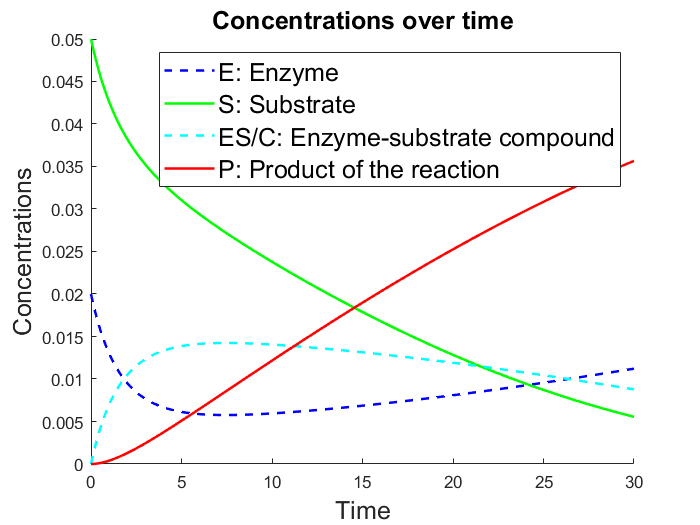


%% part a 

theta1 = 10;
theta2 = 1e-2;
theta3 = 1e-1;
e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];


ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
    (-1*theta1*x(1)*x(2)) + (theta2*x(3));
    (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
    theta3*x(3)];

[t, y] = ode45(ddt, [0 30], x0);

figure;
hold on 
plot(t, y(:,1), 'b--', 'LineWidth', 1.5)
plot(t, y(:,2), 'g', 'LineWidth', 1.5)
plot(t, y(:,3), 'c--', 'LineWidth', 1.5)
plot(t, y(:,4), 'r', 'LineWidth', 1.5)
title('Concentrations over time','Fontsize',15)
xlabel('Time','FontSize', 15)
ylabel('Concentrations','FontSize',15)
legend('E: Enzyme', 'S: Substrate', 'ES/C: Enzyme-substrate compound', 'P: Product of the reaction','FontSize',15) 
hold off

                        Figure 1: The results of the reaction solved with integration methods 

### 3. Euler's Method

Numerical iteration and knowledge of slopes can be used to approximate the solution of an initial value problem. Suppose we are given a first order equation of the following form with the corresponding initial value

$y{\;}^{\prime } \left(t\right)=f\left(t,y\left(t\right)\right)$    ;     $\left(0,y\left(0\right)\right)$  

and suppose that we wish to approximate the solution near a value of $t=0$. Since we know the true value of $y\left(t\right)\;$at $t=0\;$ and we know the derivative at this point, we can use knowledge of calculus and the tangent line to write the following equation of the tangent line to the solution at $t=0$ :


$$y\left(t\right)=y\left(0\right)+y^{\prime } \left(0\right)*\left(t-0\right)$$


Given that our subsequent value of t is close enough to our prior value, we can be assured that our approximation is fairly close to the true value of the solution at t. We can continue this approximation as many times as needed to get approximations of the desired root. 

Often, we will assume that the step sizes between subsequent values of t are uniform and thus we can replace $\left(t-0\right)=h=\frac{\left(t_n -t_0 \right)}{n}$ where n is the number of step sizes. 

Intuitively, we expect that smaller step sizes (h) will lead to more accurate approximations and flatter functions, $y\left(t\right)$, will lead to better estimates due to the fact that our calculated derivatives will closely resemble the function itself. 

In Section 3, we use the outlined Euler's Method to approximate the solution of the system of differential equations for 3 step sizes of 0.1, 1, and 2.

#### 3.1 Results with a Step Size of 0.1

Using the same initial values and system of differential equations are in Section 2, we can approximate the solution we previously found using Euler's Method. 

After defining the anonymous function, ddt, with the system of four differential equations, we create a for loop to iterate over each subsequent value of t. In each iteration, we calculate the equation of the updated tangent line and then graph the soltions found over the time span of [0,30]. Although there are very slight differences in the curves, Figure 2 almost perfectly resembles Figure 1. The black lines overlayed on the plot show the true concentration values to allow for easy comparison.

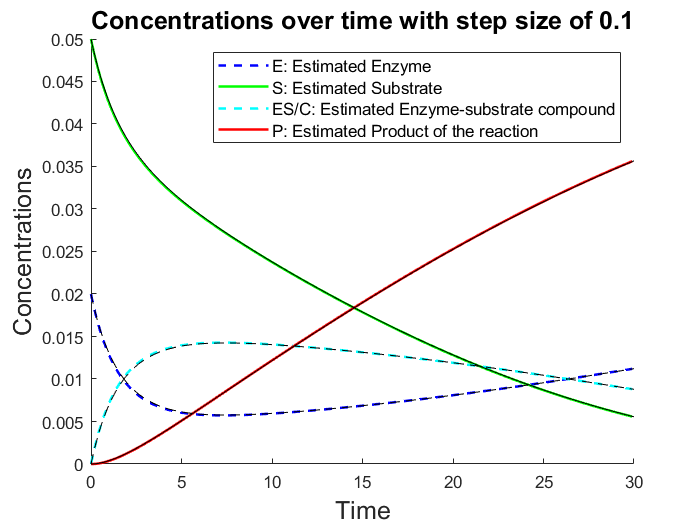


%% part b 
% step size h = 0.1
theta1 = 10;
theta2 = 1e-2;
theta3 = 1e-1;
e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];

ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
    (-1*theta1*x(1)*x(2)) + (theta2*x(3));
    (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
    theta3*x(3)]';

h1 = 0.1;
y1 = zeros((30/h1), 4);
y1(1, :) = x0';
for i=1:((30/h1) - 1)
   y1(i+1, :) =  y1(i,:) + h1 * (ddt(i*h1, y1(i,:)));
end

figure;
hold on 
plot(0:h1:30-h1, y1(:,1), 'b--', 'LineWidth', 1.5)
plot(0:h1:30-h1, y1(:,2), 'g', 'LineWidth', 1.5)
plot(0:h1:30-h1, y1(:,3), 'c--', 'LineWidth', 1.5)
plot(0:h1:30-h1, y1(:,4), 'r', 'LineWidth', 1.5)




% the true plots found with ode45
theta1 = 10;
theta2 = 1e-2;
theta3 = 1e-1;
e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];


ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
    (-1*theta1*x(1)*x(2)) + (theta2*x(3));
    (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
    theta3*x(3)];

[t, y] = ode45(ddt, [0 30], x0);


plot(t, y(:,1), 'k--', 'LineWidth', 0.5)
plot(t, y(:,2), 'k', 'LineWidth', 0.5)
plot(t, y(:,3), 'k--', 'LineWidth', 0.5)
plot(t, y(:,4), 'k', 'LineWidth', 0.5)


title('Concentrations over time with step size of 0.1','FontSize',15)
xlabel('Time','Fontsize',15)
ylabel('Concentrations','FontSize',15)
legend('E: Estimated Enzyme', 'S: Estimated Substrate', ...
    'ES/C: Estimated Enzyme-substrate compound', 'P: Estimated Product of the reaction', 'FontSize',10) 


hold off

                        Figure 2: The results of the reaction solved with Euler's Method (h = 0.1) 

#### 3.2 Results with a Step Size of 1

Below, we repeat the same steps as in 3.1 and simply replace the step size with 1 instead of 0.1. The comparison of Figure 3 with Figure 2 and Figure 1 shows a slighly more obvious difference as some of the lines become more abrupt and. This is due to the larger step size which decreases the accuracy in our approximation. The black lines overlayed on the plot show the true concentration values to allow for easy comparison.

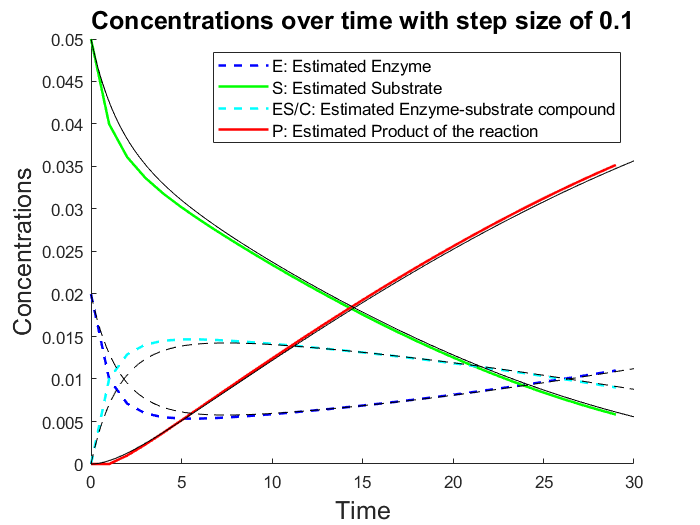


%% part b 
% step size h = 1
theta1 = 10;
theta2 = 1e-2;
theta3 = 1e-1;
e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];

ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
    (-1*theta1*x(1)*x(2)) + (theta2*x(3));
    (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
    theta3*x(3)]';

h1 = 1;
y1 = zeros((30/h1), 4);
y1(1, :) = x0';
for i=1:((30/h1) - 1)
   y1(i+1, :) =  y1(i,:) + h1 * (ddt(i*h1, y1(i,:)));
end

figure;
hold on 
plot(0:h1:30-h1, y1(:,1), 'b--', 'LineWidth', 1.5)
plot(0:h1:30-h1, y1(:,2), 'g', 'LineWidth', 1.5)
plot(0:h1:30-h1, y1(:,3), 'c--', 'LineWidth', 1.5)
plot(0:h1:30-h1, y1(:,4), 'r', 'LineWidth', 1.5)




% the true plots found with ode45
theta1 = 10;
theta2 = 1e-2;
theta3 = 1e-1;
e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];


ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
    (-1*theta1*x(1)*x(2)) + (theta2*x(3));
    (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
    theta3*x(3)];

[t, y] = ode45(ddt, [0 30], x0);


plot(t, y(:,1), 'k--', 'LineWidth', 0.5)
plot(t, y(:,2), 'k', 'LineWidth', 0.5)
plot(t, y(:,3), 'k--', 'LineWidth', 0.5)
plot(t, y(:,4), 'k', 'LineWidth', 0.5)


title('Concentrations over time with step size of 0.1','FontSize',15)
xlabel('Time','Fontsize',15)
ylabel('Concentrations','FontSize',15)
legend('E: Estimated Enzyme', 'S: Estimated Substrate', ...
    'ES/C: Estimated Enzyme-substrate compound', 'P: Estimated Product of the reaction', 'FontSize',10) 


hold off

                        Figure 3: The results of the reaction solved with Euler's Method (h = 1) 

#### 3.3 Results with a Step Size of 2

Below, we repeat the same steps as in 3.1 and 3.2 and simply replace the step size with 2. The black lines overlayed on the plot show the true concentration values to allow for easy comparison.

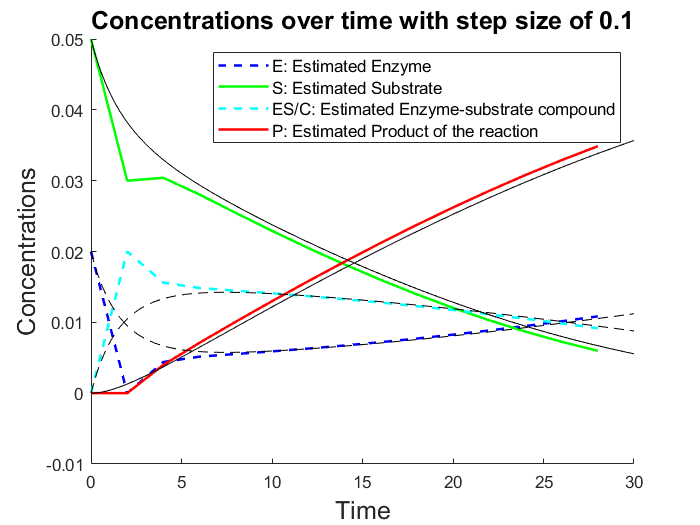


%% part b 
% step size h = 2
theta1 = 10;
theta2 = 1e-2;
theta3 = 1e-1;
e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];

ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
    (-1*theta1*x(1)*x(2)) + (theta2*x(3));
    (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
    theta3*x(3)]';

h1 = 2;
y1 = zeros((30/h1), 4);
y1(1, :) = x0';
for i=1:((30/h1) - 1)
   y1(i+1, :) =  y1(i,:) + h1 * (ddt(i*h1, y1(i,:)));
end

figure;
hold on 
plot(0:h1:30-h1, y1(:,1), 'b--', 'LineWidth', 1.5)
plot(0:h1:30-h1, y1(:,2), 'g', 'LineWidth', 1.5)
plot(0:h1:30-h1, y1(:,3), 'c--', 'LineWidth', 1.5)
plot(0:h1:30-h1, y1(:,4), 'r', 'LineWidth', 1.5)




% the true plots found with ode45
theta1 = 10;
theta2 = 1e-2;
theta3 = 1e-1;
e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];


ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
    (-1*theta1*x(1)*x(2)) + (theta2*x(3));
    (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
    theta3*x(3)];

[t, y] = ode45(ddt, [0 30], x0);


plot(t, y(:,1), 'k--', 'LineWidth', 0.5)
plot(t, y(:,2), 'k', 'LineWidth', 0.5)
plot(t, y(:,3), 'k--', 'LineWidth', 0.5)
plot(t, y(:,4), 'k', 'LineWidth', 0.5)


title('Concentrations over time with step size of 0.1','FontSize',15)
xlabel('Time','Fontsize',15)
ylabel('Concentrations','FontSize',15)
legend('E: Estimated Enzyme', 'S: Estimated Substrate', ...
    'ES/C: Estimated Enzyme-substrate compound', 'P: Estimated Product of the reaction', 'FontSize',10) 


hold off

                        Figure 4: The results of the reaction solved with Euler's Method (h = 2) 

#### 3.4 All Four Graphs Compared

Next, we have compiled all four graph into one subplot in order to easily compare them. The comparison of Figure 4 with Figures 1, 2 and 3 shows an apparent difference as the plots of the lines are no longer smooth. Rather they display sharp changes for smaller values of the time and they eventually become smoother as the time approaches 30. This is due to the much larger step size which causes the tangent line to be further from the true value of the root. However, as the number of iterations of Euler's method increases, our approximation converges to the true value of the solution which results in the smoother plots of the concentration amount. Differences between Figures 1,2, and 3 are harder to spot. If you look closely at Figure 3 with a step size of 1, you can see some sharp turns instead of curved edges. These are not as obvious as the sharp turns in Figure 4, but they are caused by the same reasons. Between Figure 1 and 2 there are no visible differences in the graphs. This is showing how accurate Euler's method can be with a small step size. 

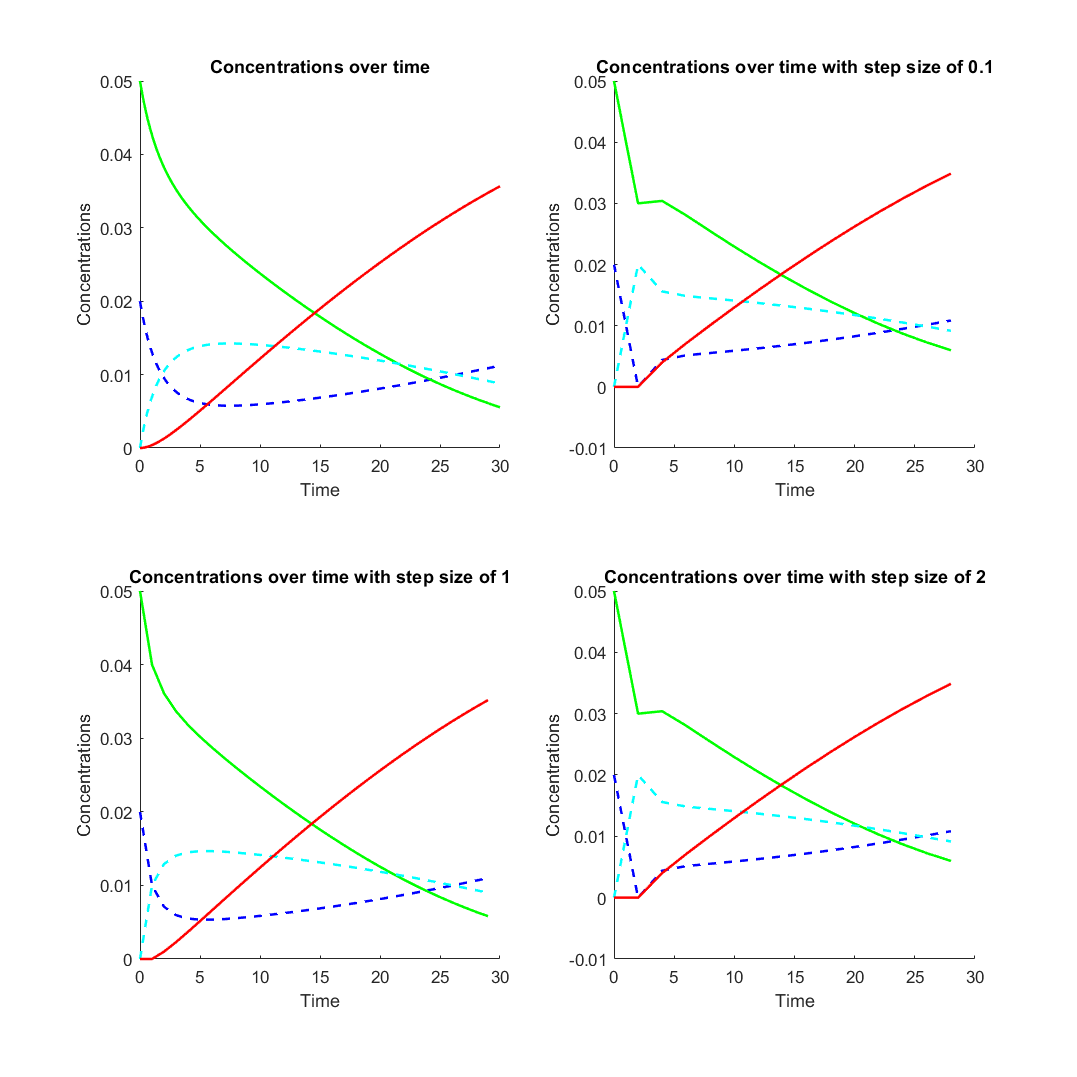

figure1=figure('Position', [1000, 1000, 1000, 1000]);
subplot(2,2,1);
hold on 
plot(t, y(:,1), 'b--', 'LineWidth', 1.5)
plot(t, y(:,2), 'g', 'LineWidth', 1.5)
plot(t, y(:,3), 'c--', 'LineWidth', 1.5)
plot(t, y(:,4), 'r', 'LineWidth', 1.5)
title('Concentrations over time')
xlabel('Time')
ylabel('Concentrations')
%legend('E: Enzyme', 'S: Substrate', 'ES/C: Enzyme-substrate compound', 'P: Product of the reaction') 
hold off

subplot(2,2,2);
hold on 
plot(0:h1:30-h1, y1(:,1), 'b--', 'LineWidth', 1.5)
plot(0:h1:30-h1, y1(:,2), 'g', 'LineWidth', 1.5)
plot(0:h1:30-h1, y1(:,3), 'c--', 'LineWidth', 1.5)
plot(0:h1:30-h1, y1(:,4), 'r', 'LineWidth', 1.5)
title('Concentrations over time with step size of 0.1')
xlabel('Time')
ylabel('Concentrations')
%legend('E: Enzyme', 'S: Substrate', 'ES/C: Enzyme-substrate compound', 'P: Product of the reaction')
hold off

subplot(2,2,3);
hold on 
plot(0:h2:30-h2, y2(:,1), 'b--', 'LineWidth', 1.5)
plot(0:h2:30-h2, y2(:,2), 'g', 'LineWidth', 1.5)
plot(0:h2:30-h2, y2(:,3), 'c--', 'LineWidth', 1.5)
plot(0:h2:30-h2, y2(:,4), 'r', 'LineWidth', 1.5)
title('Concentrations over time with step size of 1')
xlabel('Time')
ylabel('Concentrations')
%legend('E: Enzyme', 'S: Substrate', 'ES/C: Enzyme-substrate compound', 'P: Product of the reaction')
hold off

subplot(2,2,4);
hold on 
plot(0:h3:30-h3, y3(:,1), 'b--', 'LineWidth', 1.5)
plot(0:h3:30-h3, y3(:,2), 'g', 'LineWidth', 1.5)
plot(0:h3:30-h3, y3(:,3), 'c--', 'LineWidth', 1.5)
plot(0:h3:30-h3, y3(:,4), 'r', 'LineWidth', 1.5)
title('Concentrations over time with step size of 2')
xlabel('Time')
ylabel('Concentrations')

% fig = gcf;
% fig.Position(3) = fig.Position(3) + 400;
hold off

                                               Figure 5: Comparison of the reaction results among integration and Euler's Method 

### 4. Differentiation Method with Lognormal Reaction Rate Coefficients

We will now repeat the methods described above where the reaction rate coefficients can be modeled by the random variables:

#### 
$$\begin{array}{l}
\theta_1 \sim \textrm{Lognormal}\left(2\ldotp 3,0\ldotp 09\right)\\
\theta_2 \sim \textrm{Lognormal}\left(-4,1\right)\\
\theta_3 \sim \textrm{Lognormal}\left(-2,0\ldotp 09\right)
\end{array}$$
 

where a lognormal random variable with mean ($\mu$ ) and variance ($\sigma^2$ ) can be modeled by:

####    
$$e^{\mu +\sigma Z}$$


where Z is assumed to be the standard normal random variable. 

#### 4.1 Results of 50 trials 

Below, we repeat the method performed in Section 2 with MATLAB's ode45() function for a sequence of 50 trials. We overlayed the plots of all 50 trials on Figure 5 which shows that the vast majority of the plots closely resembel figure 1. However, for some randomly chosen standard normal values, the concentrations begin to deviate from the expected concentration. Furthermore, given a randomly chosen starting value of Z, if Z assumes a extreme value then the error in the concentration augments and amplifies as the time increases. 

This is clearly seen by the few lines for each component which begin to increasingly diverge as the time approaches 30. 

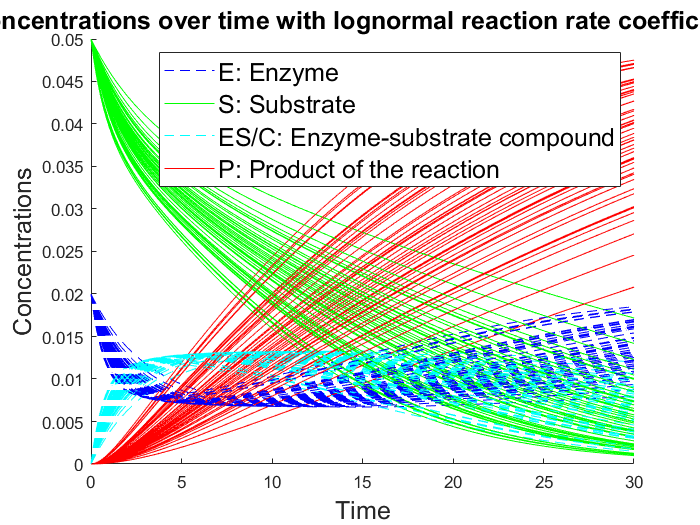


%% part c

e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];

figure;
hold on 
for numtrials = 1:50
    z = randn;
    theta1 = exp(2.3 + 0.30*z);
    theta2 = exp(-4 + 1*z);
    theta3 = exp(-2 + 0.30*z);
    ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
        (-1*theta1*x(1)*x(2)) + (theta2*x(3));
        (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
        theta3*x(3)];
    
    [t, y] = ode45(ddt, [0 30], x0);

    plot(t, y(:,1), 'b--')
    plot(t, y(:,2), 'g')
    plot(t, y(:,3), 'c--')
    plot(t, y(:,4), 'r')
end 

title('Concentrations over time with lognormal reaction rate coefficients','FontSize',15)
xlabel('Time','FontSize',15)
ylabel('Concentrations','FontSize',15)
legend('E: Enzyme', 'S: Substrate', 'ES/C: Enzyme-substrate compound', 'P: Product of the reaction','FontSize',15) 
hold off

                        Figure 6: The results of the reaction solved with integration method

                                                and lognormal reaction rate coefficients 

#### 4.2 Estimated Final Product Concentration 

The methods of Monte Carlo can be used to find an estimate for the final concentration of the product at time t = 30. In order to estimate the final product concentration, we initialize a vector to keep track of the final product concentrations of each of the 50 trials. Afterwards, we find the mean of this vector of final product concentrations which is reported as 0.0007.

By the Central Limit Theorem, the sample mean found follows a probability distribution with mean equal to the true mean of the final product concentration and standard deviation equal to the standard deviation of the final product concentration divided by the squareroot of 50 (the number of trials). 

#### 
$$\bar{x} \sim N\left(\mu \;,\frac{\sigma }{\sqrt{n}}\right)$$


Consequently, a 95% two-sided confidence interval can be constructed for the estimate found by adding and subtracting 2 standard errors from the estimate of the final product concentration. The standard error is found by taking the standard deviation of the vector of the final product concentrations and then diving by the squareroot of the length of the vector. 

In one particular random execution of the 50 trials, we found that the mean concentration is 0.0390 and the associated confidence interval is [0.0374, 0.0405]. 



%% part d

e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];

lastproduct = zeros(1,50);
for numtrials = 1:50
    z = randn;
    theta1 = exp(2.3 + 0.30*z);
    theta2 = exp(-4 + 1*z);
    theta3 = exp(-2 + 0.30*z);
    ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
        (-1*theta1*x(1)*x(2)) + (theta2*x(3));
        (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
        theta3*x(3)];
    
    [t, y] = ode45(ddt, [0 30], x0);

    lastproduct(numtrials) = y(end,4);
end 

estimated_product = mean(lastproduct);
fprintf('The expected value of the concentration of the \nproduct P at time t = 30 is %2.4f \n', estimated_product)

The expected value of the concentration of the 
product P at time t = 30 is 0.0387 


stddev_product = std(lastproduct);
standarderr_product = stddev_product / sqrt(50);
ci_lower = estimated_product - 1.96*standarderr_product;
ci_upper = estimated_product + 1.96*standarderr_product;
fprintf('The 95%% confidence interval for the expected value of the \nconcentration of the product P at time t = 30 is [%2.4f , %2.4f] \n', ci_lower, ci_upper)

The 95% confidence interval for the expected value of the 
concentration of the product P at time t = 30 is [0.0369 , 0.0405] 


### 5. Euler's Method with Lognormal Reaction Rate Coefficients 

In the following section we will approximate the solution of the final product concentrations using Euler's method combined with the Central Limit Theorem to report a final estimate of the mean concentration as well as an associated 95% confidence interval. 

For each step size, we will discuss the implications of having a computational budget of 1000 function evaluations of $f\left(t,y\left(t\right)\right)\;$as well as the tradeoffs between the Monte Carlo Method and the step size used.    

#### 5.1 Results with a Step Size of 2

Using a step size of 2 in the execution of Euler's Method permits a somewhat precise estimation of the mean final product concentration. This can be seen by the plots of the concentrations over time which show that the concentrations are very similar for initial values of time and begin to diverge as the time approaches t = 30. Initially, the individual concentration estimates are poor as can be seen by the sharp plots and steep slopes for small values of time. This is because the initially large step sizes lead to bad estimates of the concentration which eventualy converge to the true value as more iterations of Euler's Method are performed. Furthermore, the variation in the final product concentration is a consequence of randomly sampling the reaction rate coefficients from the lognormal distribution. 

In one particular random execution of 50 trials, we found that the expected value of the final concentration is 0.0384 which is only 0.0006 greater than the estimate found using the ode45() function. Additionally, the 95% confidence interval for this estimate is [0.0364, 0.0404]. The length of this confidence interval is 0.004 which is only 0.00009 wider than the confidence interval found using the ordinary differential equation solver method. 

Since the step size is 2, there are 15 computations done in each trials. Therefore, 750 evaluations are performed in in the execution of the 50 trials. This shows that we were able to find a relatively accurate result with a large step size and significantly few function evaluations. Furthermore, due to the large step size we must sacrifice some confidence in our estimate of the mean product since our confidence interval is somewhat wide. Therefore, the Monte Carlo Method allows us to find an accurate mean estimate with a larger standard error in exchange for a larger step size and fewer function evaluations.

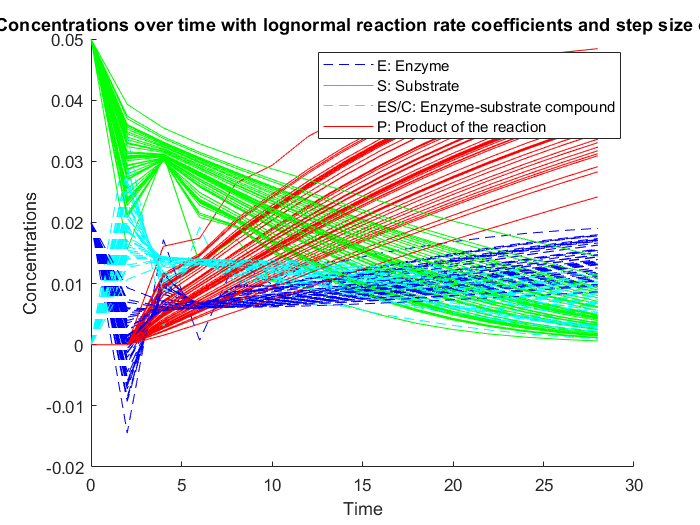

%% part e

% step size h = 2
e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];

lastproduct = zeros(1,50);
figure;
hold on 
for numtrials = 1:50
    z = randn;
    theta1 = exp(2.3 + 0.30*z);
    theta2 = exp(-4 + 1*z);
    theta3 = exp(-2 + 0.30*z);
    ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
        (-1*theta1*x(1)*x(2)) + (theta2*x(3));
        (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
        theta3*x(3)];
    
    
    h = 2;
    y = zeros((30/h), 4);
    y(1, :) = x0';
    for i=1:((30/h) - 1)
        y(i+1, :) =  y(i,:) + h * (ddt(i*h, y(i,:))');
    end

 
    lastproduct(numtrials) = y(end,4);
    
    plot(0:h:30-h, y(:,1), 'b--')
    plot(0:h:30-h, y(:,2), 'g')
    plot(0:h:30-h, y(:,3), 'c--')
    plot(0:h:30-h, y(:,4), 'r')
end 

title('Concentrations over time with lognormal reaction rate coefficients and step size of 2')
xlabel('Time')
ylabel('Concentrations')
legend('E: Enzyme', 'S: Substrate', 'ES/C: Enzyme-substrate compound', 'P: Product of the reaction') 
hold off

                        Figure 7: The results of the reaction solved with Euler's Method (h=2)

                                                and lognormal reaction rate coefficients 

#### Estimated Final Product Concentration 

estimated_product = mean(lastproduct);
fprintf('The expected value of the concentration of the \nproduct P at time t = 30 is %2.4f \n', estimated_product)

The expected value of the concentration of the 
product P at time t = 30 is 0.0397 


stddev_product = std(lastproduct);
standarderr_product = stddev_product / sqrt(50);
ci_lower = estimated_product - 1.96*standarderr_product;
ci_upper = estimated_product + 1.96*standarderr_product;
fprintf('The 95%% confidence interval for the expected value of the \nconcentration of the product P at time t = 30 is [%2.4f , %2.4f] \n', ci_lower, ci_upper)

The 95% confidence interval for the expected value of the 
concentration of the product P at time t = 30 is [0.0381 , 0.0412] 


#### 5.2 Results with a Step Size of 1

Using a step size of 1 in the execution of Euler's Method permits a more accurate estimation of the mean final product concentration with slightly more variability than the estimate found using a step size of 2. The plots of concentration over time show that the concentrations begin to vary more over time as the time approaches t = 30 in comparison with the plot in figure 7. In contrast to figure 7, the initial concentration estimates for intial values of time are more accurate due to the smaller step sizes. Furthermore, just as in figure 7, there is a large variation in the final product concentration due to the random sampling of the reaction rate coefficients from the lognormal distribution. 

In one random execution of 50 trials, we found that the resulting expected value of the final concentration is 0.0393 and the 95% confidence interval for this estimate is [0.0378, 0.0407]. The length of this confidence interval is 0.0029 which is narrower than the confidence interval found using a step size of 2. This is due to the fact that there are more function evaluations and a smaller step size. Thus there are more trials with increased accuracy which allows for a better estimate with less uncertainty. 

Since the step size is 1, there are 30 computations done in each trials. Therefore, 1,500 evaluations are performed in in the execution of the 50 trials. This shows that we were able to find a relatively accurate result with a reasonable step size and relatively few function evaluations. While this method proves to be reliable, the mean product concentration is only slightly better than the estimate found in section 5.1 and the standard error is larger. Consequently, the results of figure 8 show that figure 7 is a better estimate of the final product concentration. Using a step size of 2 enables us to get a equally precise mean estimate with a smaller standard error and fewer function evaluations. Consequently, the the fewer function evaluations enable us to find just as accurate of an estimate with less variability. 

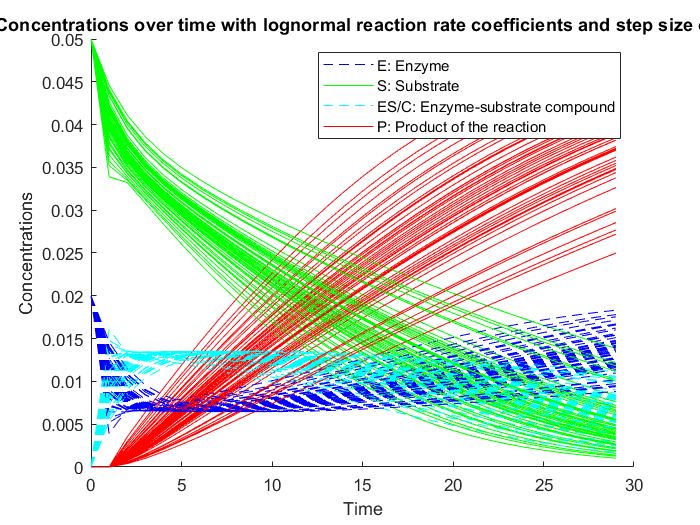

%% part e

% step size h = 1
e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];

lastproduct = zeros(1,50);
figure;
hold on 
for numtrials = 1:50
    z = randn;
    theta1 = exp(2.3 + 0.30*z);
    theta2 = exp(-4 + 1*z);
    theta3 = exp(-2 + 0.30*z);
    ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
        (-1*theta1*x(1)*x(2)) + (theta2*x(3));
        (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
        theta3*x(3)];
    
    
    h = 1;
    y = zeros((30/h), 4);
    y(1, :) = x0';
    for i=1:((30/h) - 1)
        y(i+1, :) =  y(i,:) + h * (ddt(i*h, y(i,:))');
    end

 
    lastproduct(numtrials) = y(end,4);
    
    plot(0:h:30-h, y(:,1), 'b--')
    plot(0:h:30-h, y(:,2), 'g')
    plot(0:h:30-h, y(:,3), 'c--')
    plot(0:h:30-h, y(:,4), 'r')
end 

title('Concentrations over time with lognormal reaction rate coefficients and step size of 1')
xlabel('Time')
ylabel('Concentrations')
legend('E: Enzyme', 'S: Substrate', 'ES/C: Enzyme-substrate compound', 'P: Product of the reaction') 
hold off

                        Figure 8: The results of the reaction solved with Euler's Method (h=1)

                                                and lognormal reaction rate coefficients 

#### Estimated Final Product Concentration 

estimated_product = mean(lastproduct);
fprintf('The expected value of the concentration of the \nproduct P at time t = 30 is %2.4f \n', estimated_product)

The expected value of the concentration of the 
product P at time t = 30 is 0.0384 


stddev_product = std(lastproduct);
standarderr_product = stddev_product / sqrt(50);
ci_lower = estimated_product - 1.96*standarderr_product;
ci_upper = estimated_product + 1.96*standarderr_product;
fprintf('The 95%% confidence interval for the expected value of the \nconcentration of the product P at time t = 30 is [%2.4f , %2.4f] \n', ci_lower, ci_upper)

The 95% confidence interval for the expected value of the 
concentration of the product P at time t = 30 is [0.0369 , 0.0398] 


#### 5.3 Results with a Step Size of 0.1

Using a step size of 0.1 in the execution of Euler's Method results in a less accurate estimation of the mean final product concentration which in turn has smaller variability. The plots of concentration over time show that the concentrations begin to vary more over time as the time approaches t = 30 in comparison with the plot in figure 7. In contrast to figure 7, the initial concentration estimates for intial values of time are more accurate due to the smaller step sizes. There are no sharp edges or abrupt changes in slope since the step size enables Euler's Method to smoothly converge to the true value. Furthermore, just as in figures 7 and 8, there is a large variation in the final product concentration due to the random sampling of the reaction rate coefficients from the lognormal distribution. 

In a random execution of 50 trials, we found that the resulting expected value of the final concentration is 0.0388 and the 95% confidence interval for this estimate is [0.0370, 0.0406]. The length of this confidence interval is 0.0036 which shows that this method has slightly larger standard error and uncertainty simply due to the random nature of the trials. The smaller step size permits more trials of Euler's Method and many more function evaluations which in turn causes the concentration estimates to diverge more over time. This is the emphasized the trade off between function evaluations and step size. As section 5.1 shows, if the step size is not small enough, the increase in function evaluations may cause a large uncertainty. Meanwhile, section 5.2 shows that if the step size is decreased enough then the increased function evaluations will not increase the standard error. Furthermore, figure 9 shows that decreasing the step size by too much can in fact increase the standard error. 

Since the step size is 0.1, there are 30 computations done in each trials. Therefore, 45,000 evaluations are performed in in the execution of the 50 trials. This shows that we were able to find a relatively accurate result with a small step size but significantly more function evaluations. This step size returns an equally accurate mean product concentration estimate and a much smaller associated standard error. Consequently, the results of figure 9 show that it is the best estimate of the final product concentration. In exchange for a reliable mean and small uncertainty, one must have the capabilities and resources to compute many more function evaluations. 

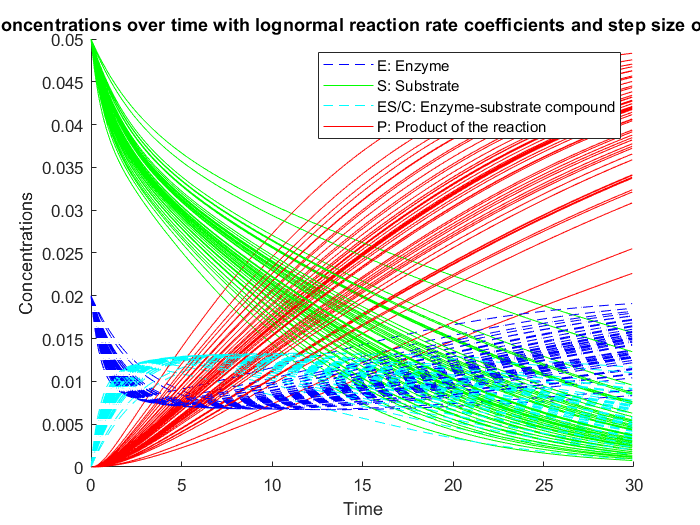

%% part e

% step size h = 0.1
e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];

lastproduct = zeros(1,50);
figure;
hold on 
for numtrials = 1:50
    z = randn;
    theta1 = exp(2.3 + 0.30*z);
    theta2 = exp(-4 + 1*z);
    theta3 = exp(-2 + 0.30*z);
    ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
        (-1*theta1*x(1)*x(2)) + (theta2*x(3));
        (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
        theta3*x(3)];
    
    
    h = 0.1;
    y = zeros((30/h), 4);
    y(1, :) = x0';
    for i=1:((30/h) - 1)
        y(i+1, :) =  y(i,:) + h * (ddt(i*h, y(i,:))');
    end

 
    lastproduct(numtrials) = y(end,4);
    
    plot(0:h:30-h, y(:,1), 'b--')
    plot(0:h:30-h, y(:,2), 'g')
    plot(0:h:30-h, y(:,3), 'c--')
    plot(0:h:30-h, y(:,4), 'r')
end 

title('Concentrations over time with lognormal reaction rate coefficients and step size of 0.1')
xlabel('Time')
ylabel('Concentrations')
legend('E: Enzyme', 'S: Substrate', 'ES/C: Enzyme-substrate compound', 'P: Product of the reaction') 
hold off

                        Figure 9: The results of the reaction solved with Euler's Method (h=0.1)

                                                and lognormal reaction rate coefficients 

#### Estimated Final Product Concentration 

estimated_product = mean(lastproduct);
fprintf('The expected value of the concentration of the \nproduct P at time t = 30 is %2.4f \n', estimated_product)

The expected value of the concentration of the 
product P at time t = 30 is 0.0401 


stddev_product = std(lastproduct);
standarderr_product = stddev_product / sqrt(50);
ci_lower = estimated_product - 1.96*standarderr_product;
ci_upper = estimated_product + 1.96*standarderr_product;
fprintf('The 95%% confidence interval for the expected value of the \nconcentration of the product P at time t = 30 is [%2.4f , %2.4f] \n', ci_lower, ci_upper)

The 95% confidence interval for the expected value of the 
concentration of the product P at time t = 30 is [0.0385 , 0.0416] 


#### 5.4 Findings From Our Experiments

In order to receive the most accurate results using Monte Carlo trials with Euler's Method, the goal is to maximize the amount of trials and lower the step size. As a consquence of our limit of 1000 function evaluations, there had to be a middle ground to both goals in order to have the most accurate output. 

When the step size was small (h=0.1), there were already 300 calculations from the time span of t=[0,30]. Therefore, a constraint of 1000 function evaluations would limit us to three trials which would result in a high standard error associated with the Monte Carlo mean estimate. Since individual estimates could vary widely and involve outliers, the small number of trials would put us at risk of having a large uncertainty. Therefore a small step size ensures that the individual estimates converge to the true values whereas we must sacrifice the number of trials we can perform. Therefore, small step sizes and precision have the drawback of larger variability. 

 When the step size was large (h=2), there were only 15 calculations from the time t=[0,30]. Therefore, a constraint of 1000 function evaluations would limit us to 66 trials which would result in a smaller standard error associated with the Monte Carlo mean estimate. Since we could sample accross 66 different trails, our estimate becomes more reliable and representative of the true value thus resulting in a smaller uncertainty. Consequently, a large step size enables us to perform more trials and decrease the variability in our estimate whereas we must sacrifice the accuracy of the individual estimates. 

With a limit of 1000 function evalutions, we are limited to a minimum step size of 1.5. Consequently, each trial would require 20 function evaluations and the 50 trials would necessitate exactly 1000 function evaluations. The results of Euler's Method with step size of 1.5 can be seen in figure 10. 

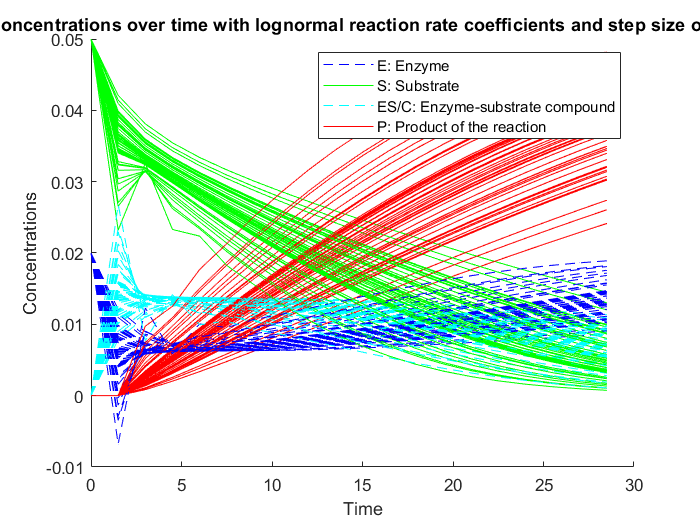

% step size h = 1.5
e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];

lastproduct = zeros(1,50);
figure;
hold on 
for numtrials = 1:50
    z = randn;
    theta1 = exp(2.3 + 0.30*z);
    theta2 = exp(-4 + 1*z);
    theta3 = exp(-2 + 0.30*z);
    ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
        (-1*theta1*x(1)*x(2)) + (theta2*x(3));
        (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
        theta3*x(3)];
    
    
    h = 1.5;
    y = zeros((30/h), 4);
    y(1, :) = x0';
    for i=1:((30/h) - 1)
        y(i+1, :) =  y(i,:) + h * (ddt(i*h, y(i,:))');
    end

 
    lastproduct(numtrials) = y(end,4);
    
    plot(0:h:30-h, y(:,1), 'b--')
    plot(0:h:30-h, y(:,2), 'g')
    plot(0:h:30-h, y(:,3), 'c--')
    plot(0:h:30-h, y(:,4), 'r')
end 

title('Concentrations over time with lognormal reaction rate coefficients and step size of 0.1')
xlabel('Time')
ylabel('Concentrations')
legend('E: Enzyme', 'S: Substrate', 'ES/C: Enzyme-substrate compound', 'P: Product of the reaction') 
hold off

                        Figure 10: The results of the reaction solved with Euler's Method (h=1.5)

                                                and lognormal reaction rate coefficients 

estimated_product = mean(lastproduct);
fprintf('The expected value of the concentration of the \nproduct P at time t = 30 is %2.4f \n', estimated_product)

The expected value of the concentration of the 
product P at time t = 30 is 0.0380 


stddev_product = std(lastproduct);
standarderr_product = stddev_product / sqrt(50);
ci_lower = estimated_product - 1.96*standarderr_product;
ci_upper = estimated_product + 1.96*standarderr_product;
fprintf('The 95%% confidence interval for the expected value of the \nconcentration of the product P at time t = 30 is [%2.4f , %2.4f] \n', ci_lower, ci_upper)

The 95% confidence interval for the expected value of the 
concentration of the product P at time t = 30 is [0.0364 , 0.0396] 


If we were given a constraint to 10,000 function evaluations, then we would be limited to a step size of 0.15. Then, every trial would require 200 function evaluations and the 50 trials would involve exactly 10,000 function evaluations. The results of Euler's Method with step size of 0.15 can be seen in figure 11. 

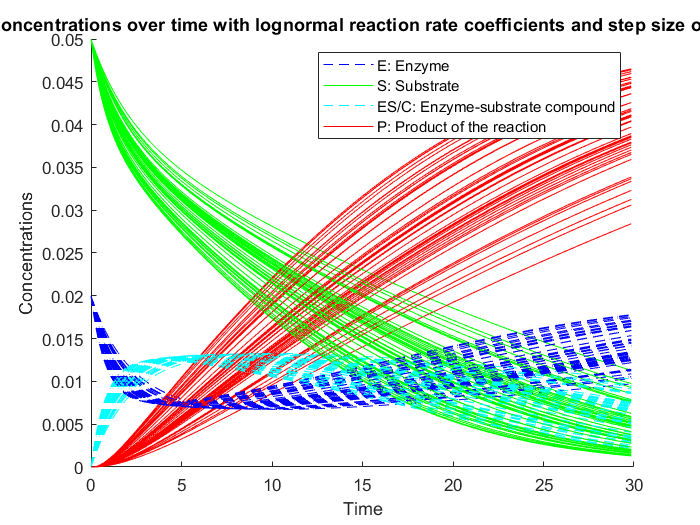

% step size h = 0.15
e0 = 2e-2;
s0 = 5e-2;
c0 = 0;
p0 = 0;
x0 = [e0;
    s0;
    c0;
    p0];

lastproduct = zeros(1,50);
figure;
hold on 
for numtrials = 1:50
    z = randn;
    theta1 = exp(2.3 + 0.30*z);
    theta2 = exp(-4 + 1*z);
    theta3 = exp(-2 + 0.30*z);
    ddt = @(t,x) [(-1*theta1*x(1)*x(2)) + ((theta2+theta3)*x(3));
        (-1*theta1*x(1)*x(2)) + (theta2*x(3));
        (theta1*x(1)*x(2)) - ((theta2+theta3)*x(3));
        theta3*x(3)];
    
    
    h = 0.15;
    y = zeros((30/h), 4);
    y(1, :) = x0';
    for i=1:((30/h) - 1)
        y(i+1, :) =  y(i,:) + h * (ddt(i*h, y(i,:))');
    end

 
    lastproduct(numtrials) = y(end,4);
    
    plot(0:h:30-h, y(:,1), 'b--')
    plot(0:h:30-h, y(:,2), 'g')
    plot(0:h:30-h, y(:,3), 'c--')
    plot(0:h:30-h, y(:,4), 'r')
end 

title('Concentrations over time with lognormal reaction rate coefficients and step size of 0.1')
xlabel('Time')
ylabel('Concentrations')
legend('E: Enzyme', 'S: Substrate', 'ES/C: Enzyme-substrate compound', 'P: Product of the reaction') 
hold off

                        Figure 11: The results of the reaction solved with Euler's Method (h=0.15)

                                                and lognormal reaction rate coefficients 

estimated_product = mean(lastproduct);
fprintf('The expected value of the concentration of the \nproduct P at time t = 30 is %2.4f \n', estimated_product)

The expected value of the concentration of the 
product P at time t = 30 is 0.0402 


stddev_product = std(lastproduct);
standarderr_product = stddev_product / sqrt(50);
ci_lower = estimated_product - 1.96*standarderr_product;
ci_upper = estimated_product + 1.96*standarderr_product;
fprintf('The 95%% confidence interval for the expected value of the \nconcentration of the product P at time t = 30 is [%2.4f , %2.4f] \n', ci_lower, ci_upper)

The 95% confidence interval for the expected value of the 
concentration of the product P at time t = 30 is [0.0389 , 0.0415] 
